3 + 5

ans = 8

# **this is a title!**

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["trial", "active_trials", "contrast_left", "contrast_right", "stim_onset", "gocue_time", "response_type", "response_time", "feedback_time", "feedback_type", "reaction_time", "reaction_type", "mouse", "session_date", "session_id"];
opts.VariableTypes = ["double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "datetime", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["active_trials", "mouse"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "session_date", "InputFormat", "yyyy-MM-dd");
opts = setvaropts(opts, "session_id", "TrimNonNumeric", true);
opts = setvaropts(opts, "session_id", "ThousandsSeparator", ",");

% Import the data
steinmetz_winter2017 = readtable("/home/ben/ibots/matlab-workshop-1/iBOTS-Intro-to-Matlab-for-Neuroscientists-main/day1/data/steinmetz_winter2017.csv", opts);

% Clear temporary variables
clear opts

% Display results
steinmetz_winter2017

steinmetz_winter2017 = 7906×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse     session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    _______    ____________    _______

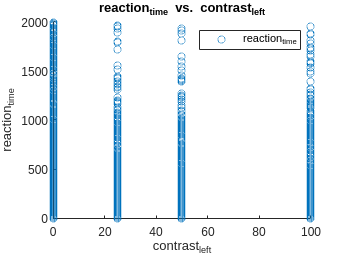

% Create scatter of selected data
s = scatter(steinmetz_winter2017,"contrast_left","reaction_time","DisplayName","reaction_time");

% Add xlabel, ylabel, title, and legend
xlabel("contrast_left")
ylabel("reaction_time")
title("reaction_time vs. contrast_left")
legend

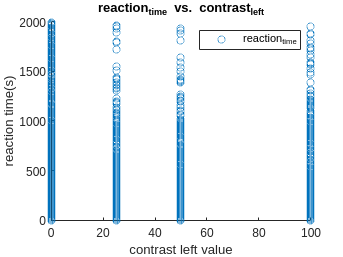


% Create scatter of selected data
s = scatter(steinmetz_winter2017,"contrast_left","reaction_time","DisplayName","reaction_time");

% Add xlabel, ylabel, title, and legend
xlabel("contrast left value")
ylabel("reaction time(s)")
title("reaction_time vs. contrast_left")
legend

## Review

a_variable = 5

a_variable = 5

my_array = [1,5,4,3,2]

my_array =      1     5     4     3     2


my_array'

ans =      1
     5
     4
     3
     2


another_array = [5,5,5,5,5]

another_array =      5     5     5     5     5


my_array * another_array'

ans = 75

my_array' * another_array

ans =      5     5     5     5     5
    25    25    25    25    25
    20    20    20    20    20
    15    15    15    15    15
    10    10    10    10    10


my_array .* another_array

ans =      5    25    20    15    10


my_array / another_array

ans = 0.6000

my_array ./ another_array

ans =     0.2000    1.0000    0.8000    0.6000    0.4000
